# How to create a publication-quality figure using Matlab

## Motivation

As humans are highly visual, good-looking figures may increase the chance that your paper look good and thus get accepted by a journal with higher impact-factor. Here I summarize tips to transform your nothing-but-ordinary figures into publication-quality ones.

## (Before formatting) Preparing a figure

Here we consider a scatter plot with a linear regression line as an example. It looks as follows:

% create an example scatter plot with a linear regression line ------------
% data generation
rng(20180301)
x = rand(30, 1);
y = 0.6*x + 0.4*rand(30, 1);

% Spearman correlation
[r_corr, p_corr] = corr(x, y, 'type', 'Spearman');

% linear regression
b = glmfit(x, y, 'normal', 'link', 'identity', 'constant', 'on');

% Wilcoxon rank sum test
p = ranksum(x,y);


% plot unity line
plot(xrange, yrange, '-', 'color', 0.4*ones(1,3),'linewidth', 0.5)
hold on;


% plot the regression line
xrange = [0, 1];
plot(xrange, glmval(b, xrange, 'identity'), '-r', 'linewidth', 0.5)
hold on;

% create a figure
scatter(x, y, 30, 'markerfacecolor', 'r', 'markerfacealpha', 0.4, ...
    'markeredgecolor', 'w', 'markeredgealpha', 0.8)
hold on;

% formatting axis
yrange = xrange;
text(0.6*xrange(2), 0.2*yrange(2), ['rho=' num2str(r_corr) ', p=' num2str(p_corr)])
text(0.6*xrange(2), 0.1*yrange(2), ['ranksum: p=' num2str(p)])
xlim(xrange)
ylim(yrange)
xlabel('x')
ylabel('y')
title('my data')

## General formatting tips

A figure looks typically better when:

- ticks are oriented outside

- box is off

- axis is square

- Fonts are same across all the labels and texts (Font size of 6 is a nice choice basically for many journals)

- Tick labels at most 3 in each axis

These can be achieved easily as follows:

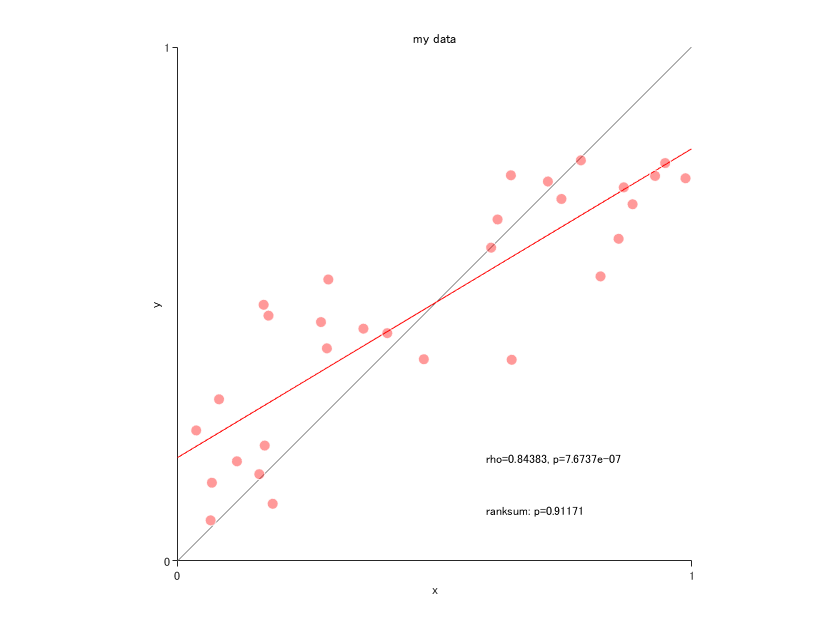

% ticks orienting outward
set(gca, 'TickDir', 'out')

% box off
set(gca, 'box', 'off')

% square axis
axis square

% same font size (this time 6)
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 6)

% two tick-labels in each axis
set(gca, 'XTick', xrange)
set(gca, 'YTick', yrange)

The figure looks already better. The font size looks too small, but that's fine for now.

## Copy axes 

Typically there are multiple panels in your figure. The way to arrange such spatial relations in a way that you like is copy axes. Essentially you copy your figures and put them in a plain background.

First we define some figure parameters, which can be accepted by many journals.

% figure parameters
figpar.Color =         'w';
figpar.Units =         'centimeters';
figpar.PaperUnits =    'centimeters';

% axis parameters 
axispar.xcolor = 'k';
axispar.ycolor = 'k'; 
axispar.TickDir = 'out';
axispar.TickLength = [0.02 0.02];
axispar.Box = 'off';
axispar.Units = 'centimeters';
axispar.FontName= 'Arial';

% font size & line width for a paper
axispar.paper.fontsize = 6;
axispar.paper.linewidth = 0.5;

% % font size & line width for a poster
% axispar.poster.fontize = 24;
% axispar.poster.linewidth = 2;

## Introduce offset axis

One final push is to introduce an offset of your x- and y-axis. This is quite a minor change in your figure, but indeed your figure would look better in the end. As you go through the following tidious manipulations on parameters in your figure axes, you can achieve that.

% get the current axes
h = gca;

% offset (currently 5%); shift percentage of x- and y-axis (0 - 1)
shift_percentage = [0.05, 0.05];

box off
axis off       

base_pos = get(h,'position');

expos_1 = base_pos;
expos_1(1) = expos_1(1)-expos_1(3)*shift_percentage(1);
expos_1(3) = 1/10^10;
a1 = axes(axispar,'position', expos_1);
expos_2 = base_pos;
expos_2(2) = expos_2(2) - expos_2(4)*shift_percentage(2);
expos_2(4) = 1/10^10;
a2 = axes(axispar,'Position', expos_2);

set(a2,'xtick',get(h,'xtick'),'xticklabel',get(h,'xticklabel'))
set(a2,'xlim',get(h,'xlim'))
set(a2,'xlabel',get(h,'xlabel'))
set(a2,'ticklength', axispar.TickLength)

set(a1,'ytick',get(h,'ytick'),'yticklabel',get(h,'yticklabel'))
set(a1,'ylim',get(h,'ylim'))
set(a1,'ylabel',get(h,'ylabel'))
set(a1,'ticklength', axispar.TickLength)